# Example: MHKiT-MATLAB WEC-Sim

This example loads simulated data from a [WEC-Sim](http://wec-sim.github.io/WEC-Sim/index.html) run for a two-body point absorber [(Reference Model 3)](http://wec-sim.github.io/WEC-Sim/tutorials.html#two-body-point-absorber-rm3) and demonstrates the application of the [MHKiT wave module](https://mhkit-software.github.io/MHKiT/mhkit-python/api.wave.html) to interact with the simulated data. The analysis is broken down into  three parts: load WEC-Sim data, interact with the WEC-Sim data, and apply the MHKiT wave module.

- Load WEC-Sim Simulated Data

- Analyze WEC-Sim Simulated Data  (e.g. Wave Class, Body Class, PTO Class, Constraint Class, and Mooring Class Data)

- Apply MHKiT Wave Module

## 1. Load WEC-Sim Simulated Data

WEC-Sim saves output data as a MATLAB output object, generated by WEC-Sim’s [Response Class](http://wec-sim.github.io/WEC-Sim/api.html#response-class). The WEC-Sim output object contains data for: `wave, bodies, ptos, constraints, mooring, moordyn, and ptosim`

Here we will load the WEC-Sim RM3 data run with a mooring matrix.

filename = '.\data\RM3MooringMatrix_matlabWorkspace.mat'
load(filename,'output')

output =   responseClass with properties:

           wave: [1×1 struct]
         bodies: [1×2 struct]
           ptos: [1×1 struct]
    constraints: [1×1 struct]
        mooring: [1×1 struct]
        moorDyn: [1×1 struct]
         ptosim: [1×1 struct]


output

## 2. Analyze WEC-Sim Simulated Data

This section will analyze the WEC-Sim RM3 data using the WEC-Sim output object. 

### **Wave Class Data**

Data from WEC-Sim’s [Wave Class](http://wec-sim.github.io/WEC-Sim/code_structure.html#wave-class) includes information about the wave input, including the the wave `type`, and wave `elevation` as a function of `time`. 

% Store WEC-Sim output from the Wave Class to a new variable, called `wave_data`
wave_data = output.wave

wave_data = struct with fields:
         type: 'etaImport'
         time: [40001×1 double]
    elevation: [40001×1 double]


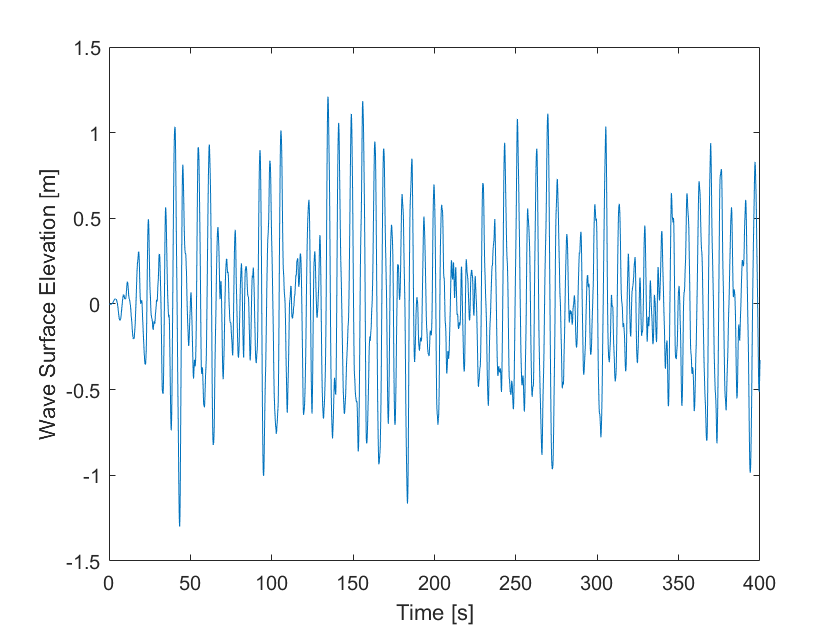

figure;plot(wave_data.time,wave_data.elevation)
xlabel("Time [s]")
ylabel("Wave Surface Elevation [m]")

### **Body Class Data**

Data from WEC-Sim’s [Body Class](http://wec-sim.github.io/WEC-Sim/code_structure.html#body-class) includes information about each body, including the body’s position,  velocity, acceleration, forces acting on the body, and the body’s name.  For the RM3 example there will be 2 boides a float and a spar.

bodies = output.bodies

bodies = 1×2 struct array with fields:
    name
    time
    position
    velocity
    acceleration
    forceTotal
    forceExcitation
    forceRadiationDamping
    forceAddedMass
    forceRestoring
    forceMorrisonAndViscous
    forceLinearDamping


body1 = output.bodies(1)

body1 = struct with fields:
                       name: 'float'
                       time: [40001×1 double]
                   position: [40001×6 double]
                   velocity: [40001×6 double]
               acceleration: [40001×6 double]
                 forceTotal: [40001×6 double]
            forceExcitation: [40001×6 double]
      forceRadiationDamping: [40001×6 double]
             forceAddedMass: [40001×6 double]
             forceRestoring: [40001×6 double]
    forceMorrisonAndViscous: [40001×6 double]
         forceLinearDamping: [40001×6 double]


## 3. Apply MHKiT Wave Module

% Use the MHKiT Wave Module to calculate the wave spectrum from the WEC-Sim Wave Class Data
sample_rate=60
nnft=1000        % Number of bins in the Fast Fourier Transform

sample_rate = 60

ws_spectrum = elevation_spectrum(wave_data.elevation, sample_rate, nnft,wave_data.time)

nnft = 1000

% Plot calculated wave spectrum

ws_spectrum = struct with fields:
       spectrum: [501×1 double]
           type: 'Spectra from Timeseries'
      frequency: [501×1 double]
    sample_rate: 60
           nnft: 1000


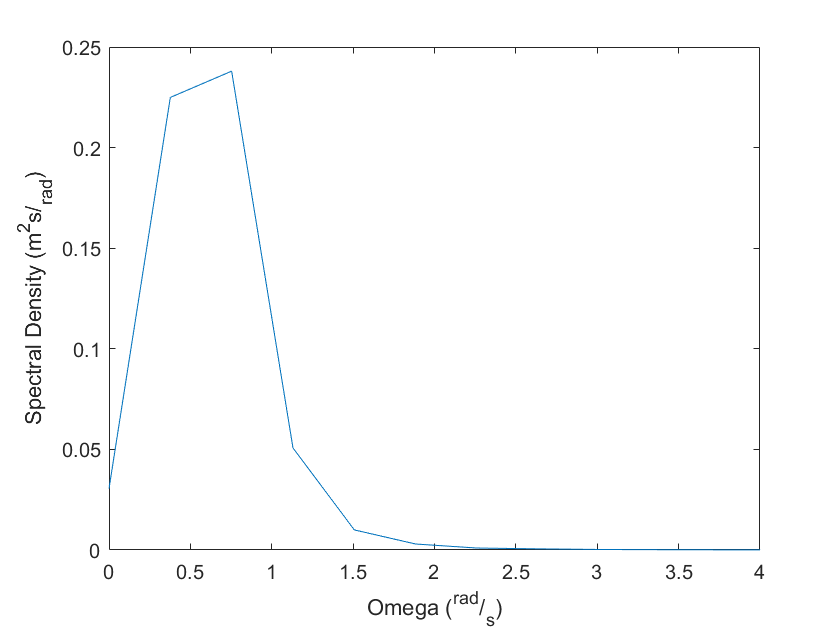

spect_plot = plot_spectrum(ws_spectrum);xlim([0, 4]);

% Calculate Peak Wave Period (Tp) and Significant Wave Height (Hm0)
Tp = peak_period(ws_spectrum)
Hm0 = significant_wave_height(ws_spectrum)

    8.3333



Tp = 8.3333

Hm0 = 1.7857

filename = '.\data\RM3MooringMatrix_matlabWorkspace.mat'